# Task 1

### Load the images and displaying them

Here are the two images that will be used for task1

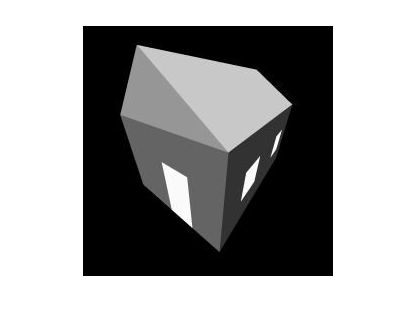

house_left = imread("../left.jpg");
cameraman = imread("cameraman.tif");
figure;
imshow(house_left);

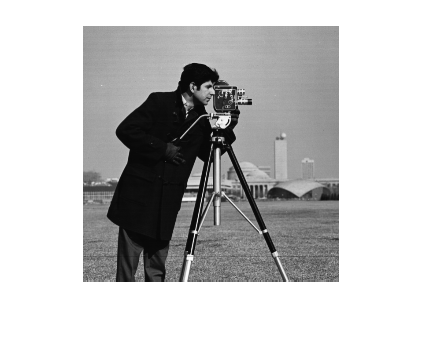

figure;
imshow(cameraman);

First we generate their histograms

house_hist = imhist(house_left);
camera_hist = imhist(cameraman);

Then generate their thresholds, first the house:

[t_house,gm_house] = otsu_thresh(house_hist);
fprintf("House threshold = %d, goodness = %f",t_house,gm_house);

House threshold = 4, goodness = 0.855831

Then do the same for the camera man:

[t_camera,gm_camera] = otsu_thresh(camera_hist);
fprintf("Cameraman threshold = %d, goodness = %f",t_camera,gm_camera);

Cameraman threshold = 82, goodness = 0.846090

Display the thresholded house

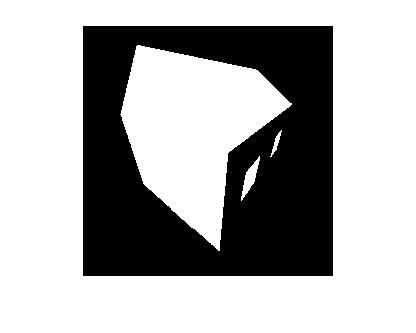

figure;
imshow(house_left>t);

Display the thresholded cameraman

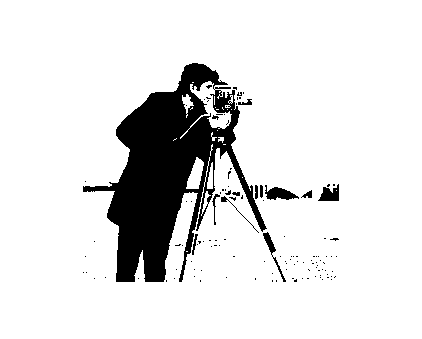

figure;
imshow(cameraman>t);

Not sure what to comment on here, the otsu thresh function produces the expected result, it runs in O(n) time which is quite good. 

Here is the code used for otsu thresh

### Comparing to the matlab function

Calling the function according to the exmaple provided in the graythresh function

threshold = graythresh(cameraman);
BW = imbinarize(cameraman,level);
fprintf("Matlabs cameraman threshold = %d",floor(threshold*255));

Matlabs cameraman threshold = 88

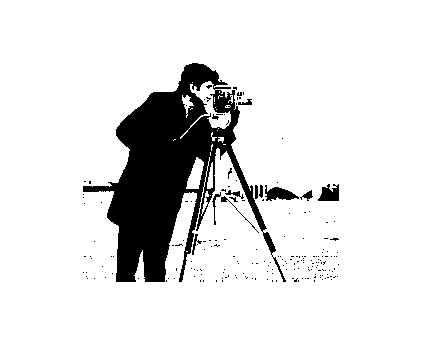

figure, imshow(BW)

The matlab "otsuthresh" function is a lot more efficient than my implementation. It seems to use bucket sort idea's, and is verry heavely inspired by the original paper.